# PRACTICA 1

# Ejercicio 1.1

En la primera parte del ejercicio vamos a cargar, escuchar y visualizar las señales

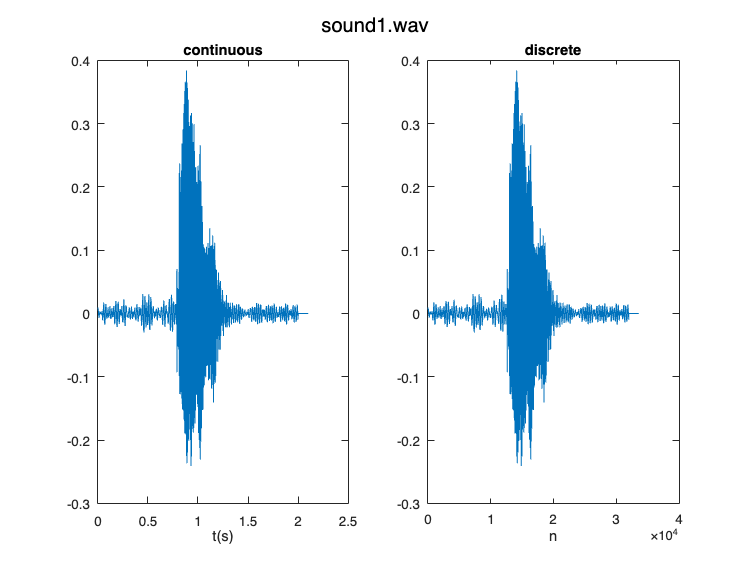

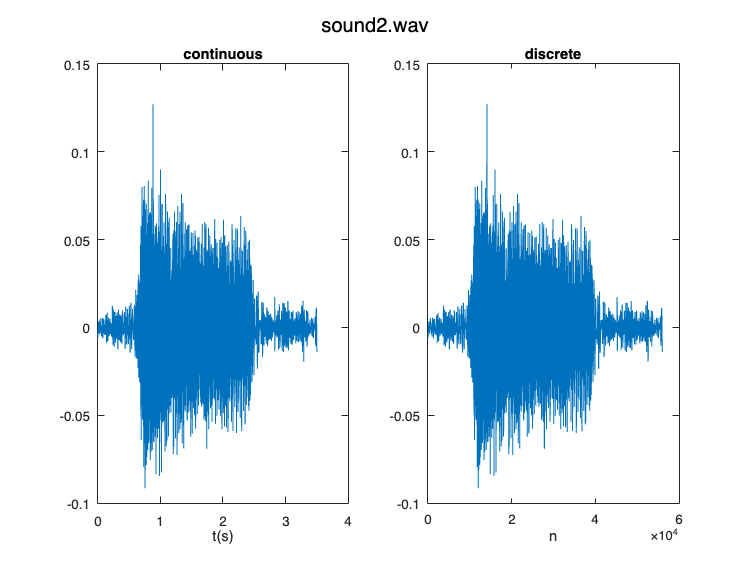

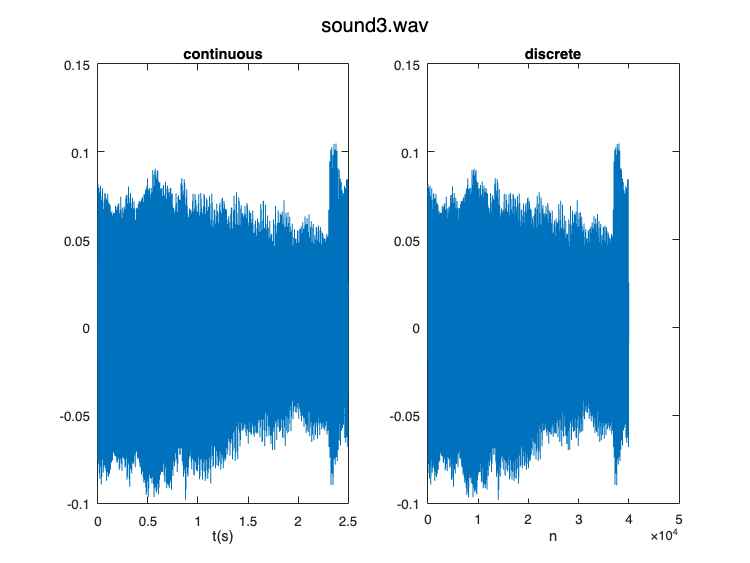

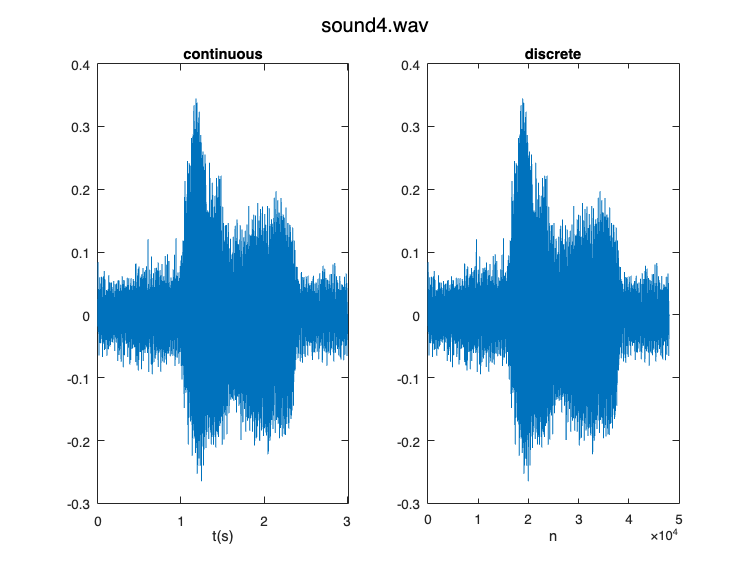

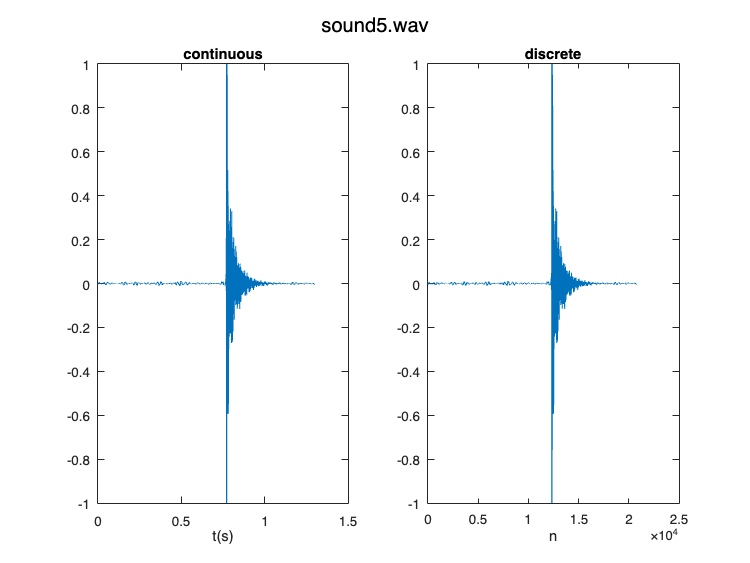

sound_files = dir('audio/*.wav');

for file = 1:length(sound_files)
    file_path = strcat('audio/', sound_files(file).name);
    [y, fs] = audioread(file_path);

    figure
    sgtitle(sound_files(file).name)

    subplot(1, 2, 1)
    dibuja(y, fs)
    title("continuous")
    xlabel("t(s)")

    subplot(1, 2, 2)
    plot(y)
    title("discrete")
    xlabel("n")


    sound(y, fs)
    % pause(5)
end

# Ejercicio 1.2

En este ejercicio y el siguiente usaremos solo los sonidos almacenados en y1, y2 e y3. 

Crea los vectores yframe1, yframe2 e yframe3 de forma que cada uno de ellos contenga **un tramo de 100ms** de la señal correspondiente **en donde aparezca sonido**. 

Dibújalos en figuras independientes con el eje temporal en segundos (usa dibuja.m)

[y1, fs1] = audioread('audio/sound1.wav');
[y2, fs2] = audioread('audio/sound2.wav');
[y3, fs3] = audioread('audio/sound3.wav');
y1(1)

ans = 0.0084

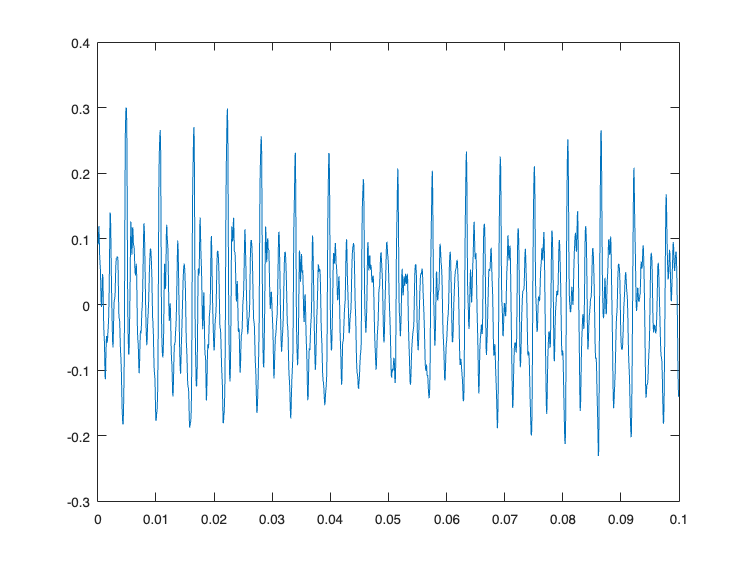


L_frame1 = round(0.1*fs1);
L_frame2 = round(0.1*fs2);
L_frame3 = round(0.1*fs3);

L_duration1 = 512/fs1;
L_duration2 = 512/fs2;
L_duration3 = 512/fs3;

yframe1 = y1(15000:15000 + L_frame1);
yframe2 = y2(14000:14000 + L_frame2);
yframe3 = y3(1000:1000 + L_frame3);

figure
dibuja(yframe1, fs1)

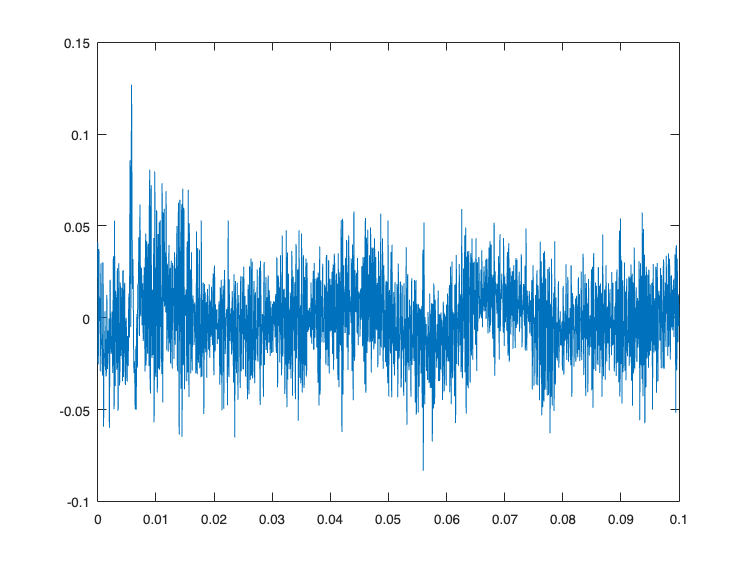

dibuja(yframe2, fs2)

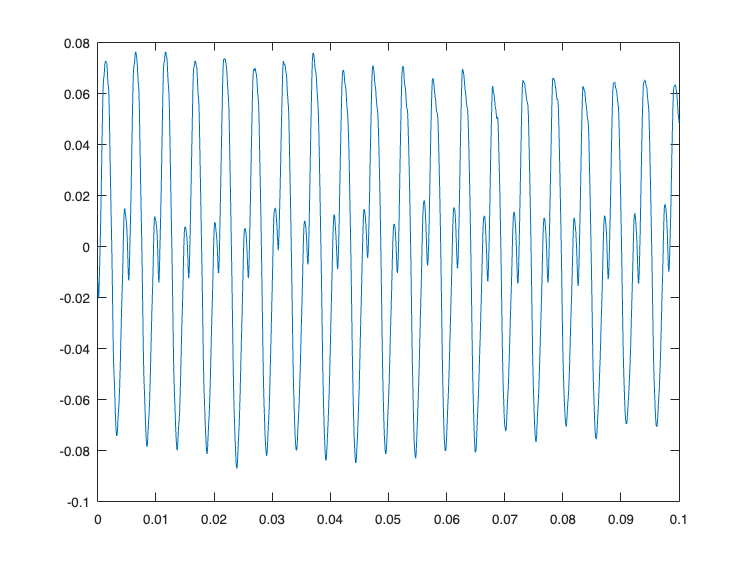

dibuja(yframe3, fs3)

¿Cuáles tienen estructura periódica? A partir de lo que ves, estima cuál es el periodo fundamental de las que son periódicas, T, y calcula su frecuencia fundamental, f0, como el inverso de T. Explica brevemente como has hecho los cálculos.

Calcula la potencia media y la energía  de las señales y1, y2, y3

P1 = mean(y1 .^ 2)

P1 = 0.0014

P2 = mean(y2 .^ 2)

P2 = 2.3102e-04

P3 = mean(y3 .^ 2)

P3 = 0.0018


E1 = sum(y1 .^ 2)

E1 = 45.9239

E2 = sum(y2 .^ 2)

E2 = 12.9372

E3 = sum(y3 .^ 2)

E3 = 70.5178

# Ejercicio 1.3

En este ejercicio vamos a realizar el **procesado digital de las señales por tramas**. Para ello vamos a realizar una funcion que descomponga una señal en tramas sin solape empleando la funcion de matlab **reshape**. En caso de que el número de muestras de la señal no sea un múltiplo entero de la longitud de la trama deberás rellenar con ceros la señal **previamente**. 

En esta funcion NO PUEDES EMPLEAR BUCLES

La cabecera de la funcion será la siguente:

El resultado de la funcion es una matriz en la que cada columna contiene las muestras de cada trama. **Escribe al final de este livescript el código de la función.**

Una vez descompuesta una señal en tramas, **se puede visualizar cómo varía su energía en el tiempo** calculando la energía de sus tramas (para ellos usa la función sum). El resultado para cada señal será **un vector E **cuya longitud será el número de tramas y en cada elemento tendremos la energia de cada trama.

La longitud de cada vector E es distinta para cada señal porque los sonidos también tienen distinta duración. Se pueden dibujar vectores de distinta longitud en una misma figura usando el comando hold. Busca en la documentación de Matlab como se usa hold y dibuja las tres energías en una misma figura con un eje de tiempos discreto. Comenta la diferencia entre ellas.


dur_trama = 0.1; % 100 ms

% Descomponer las señales y1, y2, y3 en tramas 
%   mediante la función tramas_sin_solape



% Calcular los vectores de energia por trama E1, E2 E3 para cada señal



% Representar los vectores en un mismo plot empleando la funcion hold y
% tiempo discreto





A continuación representaremos los vectores de energía empleando tiempo continuo con la función dibuja que has programado anteriormente. Recuerda que  el tiempo entre tramas es 100 ms, por lo que tienes que crear un eje de tiempos en segundos distinto del usado para los sonidos.

# Ejercicio 1.4

En este ejercicio **vamos a permitir que las tramas tengan solape**. La idea general es que en la trama m-ésima no todas las muestras son nuevas, sino que se seleccionan algunas muestras de la trama anterior (m-1) y el resto son muestras nuevas. En la figura se han seleccionado la mitad (L_frame/2) muestras de la trama anterior y (L_frame/2) muestras nuevas. Se dice entonces que el solape (overlap) es del 50%. 

Para realizar el ejercicio debes realizar previamente una **funcion llamada tramas_con_solape** que descomponga la señal en las tramas con solape. La funcion tiene esta estructura:

El resultado de la funcion es una matriz en el que cada columna contiene las muestras de cada trama. **Escribe al final de este livescript el código de la función.**

Dibuja las energías de las señales y1, y4 e y5 descompuestas con la función anterior en una misma figura con un eje de tiempos continuo. 

Ten en cuenta el salto de tiempos entre tramas que es distinto de cuando usabas la función `tramas_sin_solape`

Comenta las diferencias entre señales.

% Descomponer las señales y1, y4, y5 en tramas con solape del 50%, y
% calcular las energias de cada trama




% Representar las señales en la misma grafica 
%      con el eje de abscisas en segundos. 
% Tener en cuenta el avance de cada frame 




Copia aquí las funciones que te piden en la práctica.

DIBUJA

function dibuja (y1, fs) 
    Ly = length(y1);
    t = (0:Ly-1)/fs;
    
    plot(t, y1);
end

TRAMAS_SIN_SOLAPE

TRAMAS_CON_SOLAPE